**Answer Key**

Here are al the answers for all the problems, feel free to use it to check your work.

**Part 1:**

  clear; % Clear old variables (helps with stability)

% A framework for your function is given
function approximate = maclaurin(fun, n)
    % INPUT:
    %      fun: a symbolic function to approximate
    %      n: the order to approximate the function to (starting at 0)
    % OUTPUT
    %      approximate: a symbolic approximation of fun using n+1 terms
    syms x 
    
    approximate = 0;
    for i = 0:n
        approximate = approximate + subs(diff(fun,i),0)/factorial(i) * x^i;
    end

  

end

% Here is a test case for your function (DO NOT CHANGE)
syms x
f = 5*x^3 - 6*x^2 + 3*x - 4;

% You can experiment with different n values here
n = 1; % Values greater than 3 should not return new answers
maclaurin(f,n)

$$ans = 3\,x-4$$


% Run Tests on your function (DO NOT CHANGE)
assert(maclaurin(f,0) == -4, ' should return -4 i.e. f(0)')
assert(maclaurin(f,1) == 3*x-4, 'This should return 3x-4')
assert(maclaurin(f,2) == -6*x^2+3*x-4,'This should return -6x^2 + 3x - 4')
assert(maclaurin(f,3) == 5*x^3-6*x^2+3*x-4, 'This should return 5x^3 - 6x^2 + 3x - 4')
disp('All Tests Passed!');

All Tests Passed!






clear; % Clear old variables (helps with stability)

% A framework for your function is given
function approximate = taylor(fun, n, c)
    % INPUT:
    %      fun: a symbolic function to approximate
    %      n: the order to approximate the function to (starting at 0)
    %      c: the point at which to approximate fun
    % OUTPUT
    %      approximate: a symbolic approximation of fun at c using n+1 terms
    syms x 
  
    approximate = 0;
    for i = 0:n
        approximate = approximate + subs(diff(fun,i),c)/factorial(i) * (x-c)^i;
    end

end

% Here is a test case for your function (DO NOT CHANGE)
syms x
f = 0.1*x^4 + 0.5*x^3 - 3*x - 2;

% You can experiment with different n and c values here
n = 0;
c = 2;
taylor(f,n,c)

$$ans = -\frac{12}{5}$$


% Run Tests on your function (DO NOT CHANGE)
assert(taylor(f,0,0) == -2, ' should return 2')
assert(taylor(f,0,2) == -12/5, 'This should return -12/5 or -2.4')
assert(simplify(taylor(f,1,1)) == -11/10*x-33/10, 'This should return -11x/10 - 33/10')
assert(simplify(taylor(f,2,-2)) == (-3/5)*x^2-(13/5)*x-(6/5),'This should return (-3/5)*x^2 - (13/5)*x - (6/5)')
disp('All Tests Passed!');

All Tests Passed!


**Part 2:**

% The arrays `RPM_Scaled` and `Torque_out` contain test bench measurements 
% from the Baja car's Continuous Variable Transmission (CVT) system. 
% Your task is to fit a quadratic curve (2nd Degree) to this data to create 
% a predictive mathematical model for the torque output.

RPM_Scaled = [1, 2, 3, 4, 5];
Torque_Out = [2, 5, 10, 17, 26];

% TASK 1: 
% Use the polyfit function to find the coefficients of a 2nd Degree 
% polynomial that best fits the data above. 
% Assign the resulting vector to a variable named 'CVT_Coeffs'.

CVT_Coeffs = polyfit(RPM_Scaled,Torque_Out,2)% YOUR CODE HERE

CVT_Coeffs =     1.0000   -0.0000    1.0000


RPMToTorque = @(R) polyval(CVT_Coeffs,R);

% TASK 2: 
% A new test run had the engine operating at a scaled RPM of 3.5. 
% Use the polyval function and your newly created 'CVT_Coeffs' model 
% to estimate the output torque at this specific RPM. 
% Assign the result to a variable named 'Estimated_Torque'.

Target_RPM = 3.5;
Estimated_Torque = RPMToTorque(Target_RPM)% YOUR CODE HERE

Estimated_Torque = 13.2500

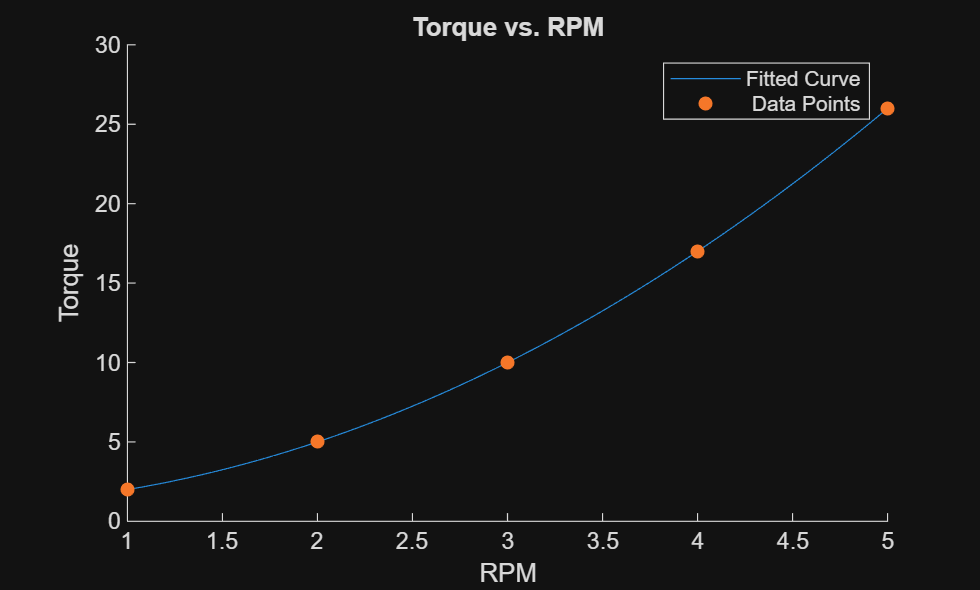


% TASK 3:
% Let's visualize the fit! First, create a dense array of RPM values 
% to plot a perfectly smooth curve. 
% 1. Create a vector of 100 points between 1 and 5 and name it 'RPM_Range'.
% 2. Evaluate your 'CVT_Coeffs' model over 'rpm_fine' and name it 'Torque_Range'.
% 3. Plot the original data points as circles, and the fitted curve as a solid line.
%    (Don't forget to add a legend, title, and axis labels!)

RPM_Range = linspace(1,5,100);% YOUR CODE HERE
Torque_Range = (RPMToTorque(RPM_Range));% YOUR CODE HERE

% YOUR PLOTTING CODE HERE:
figure
hold on
plot(RPM_Range,Torque_Range)
scatter(RPM_Scaled,Torque_Out,'filled')
legend('Fitted Curve', ' Data Points')
xlabel('RPM')
ylabel('Torque')
title('Torque vs. RPM')
hold off


% =========================================================================
% --- DO NOT MODIFY BELOW THIS LINE ---
% Assertion Tests
% Run this section to verify your answers. If you do not see any red error 
% text, your code is correct!
% =========================================================================

assert(exist('CVT_Coeffs', 'var') == 1, 'Variable CVT_Coeffs does not exist. Did you name it correctly?');
assert(length(CVT_Coeffs) == 3, 'CVT_Coeffs should have exactly 3 elements for a 2nd-degree polynomial.');
assert(abs(CVT_Coeffs(1) - 1) < 1e-4, 'Your polynomial coefficients appear incorrect. Double-check your polyfit inputs and the specified degree.');

assert(exist('Estimated_Torque', 'var') == 1, 'Variable Estimated_Torque does not exist. Did you name it correctly?');
assert(abs(Estimated_Torque - 13.25) < 1e-4, 'Your estimated torque is incorrect. Double-check how you are using polyval with the Target_RPM.');

disp('All tests passed! Excellent work.')

All tests passed! Excellent work.


**Part 3:**

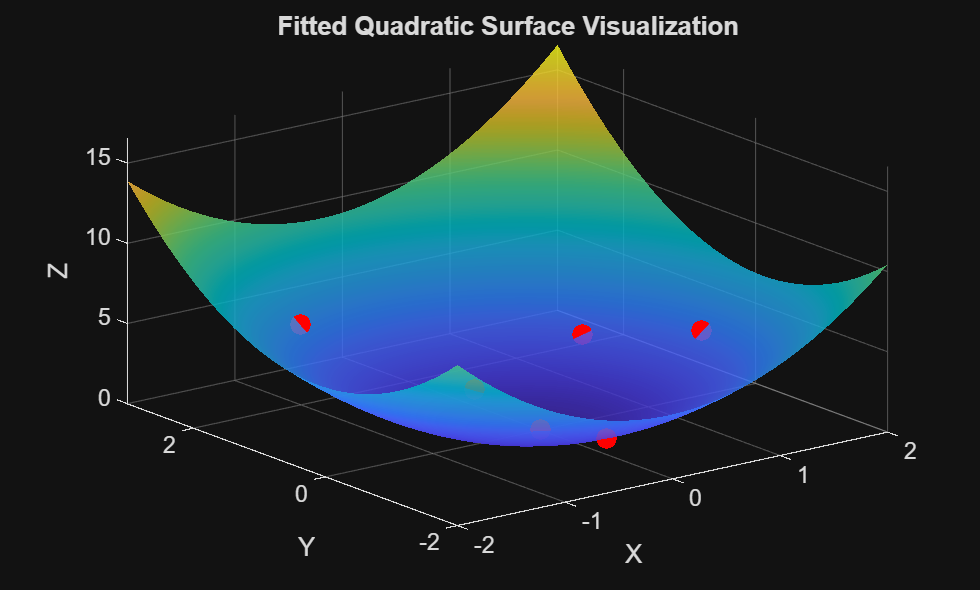

% Define the data points
x = [0 1.5 0 -1 0 1];
y = [0 0 1 2 -1 1];
z = [0 4 1 5 1 3];
% Consider reformating/restructuring the data to make it easier to
% manipulate
x = x';
y = y';
z = z';
% Build the X and Z matrix
% X needs 6 columns for a quadratic fit: [1, x, y, x^2, y^2, xy]
X = [ones(size(x)), x, y, x.^2, y.^2, x.*y];
Z = z;
% Solve for the 6 coefficients
% Using the backslash operator for Ordinary Least Squares
QuadCoeff = X \ Z;
% Create an anonymous function using the solved coefficients
% make sure to use element-wise operators (.^ and .*) for fsurf compatibility
fittedSurface = @(x, y) QuadCoeff(1) + ...
 QuadCoeff(2)*x + ...
 QuadCoeff(3)*y + ...
 QuadCoeff(4)*x.^2 + ...
 QuadCoeff(5)*y.^2 + ...
 QuadCoeff(6)*x.*y;
% Now visualize your function using fsurf
% Adjusted bounds slightly to capture all data points well
fsurf(fittedSurface, [-2 2 -2 3], 'FaceAlpha', 0.8, 'EdgeColor', 'none')
hold on
scatter3(x, y, z, 75, 'filled', 'r') % Overlay original data points
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Fitted Quadratic Surface Visualization');
grid on;
hold off

**Part 4:**